# Lecture: MATLAB Review 3 Code

## Formatting values using fprintf

fprintf('The value of pi is ___.\n')

The value of pi is ___.


## while loop - projectile example

The Cartesian coordinates of a projectile launched with an initial velocity ($v_0$) and angle ($\theta_0$) can be computed with: 

$x=v_0 \;\cos \left(\theta_0 \right)t$, $y=v_0 \;\sin \left(\theta_0 \right)t-0\ldotp 5{\textrm{gt}}^2$

***At what time (to the nearest 100th of a second) will the projectile hit the ground if ***$v_0 =5\;$***m/s and ***$v_0 =50\degree$***?***

v0 = 5; % initial velocity [m/s]
theta0 = 50; % initial angle [in degrees]
g = 9.81; % accel. due to gravity [m/s/s]
t = 0.01;
y = @(t) v0*sind(theta0)*t - 0.5*g*t^2;
height = y(t);

while height > 0
    t = t + 0.01;
    height = y(t);
end

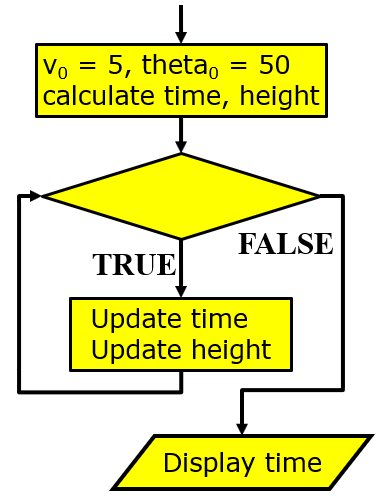


fprintf('The ball will hit the ground at %.2f seconds', t)

The ball will hit the ground at 0.79 seconds

## while-break loop - divide and average example

The square root for any positive #, $a$, can be approximated by: $x=\frac{x+\frac{a}{x}}{2}$  

The error can be calculated using: $\varepsilon =\left|\frac{x_{\textrm{new}} -x_{\textrm{old}} }{x_{\textrm{new}} }\right|$ 

***Evaluate ***$a=5$*** for ***$\varepsilon ={10}^{-3}$

a = 5;
errTol = 10^-3;
x = a/2; % start out by dividing


while true
    x0 = x;
    x = (x0 + a/x0)/2;
    err = abs((x0-x)/x);
    if err < errTol
        break
    end
end

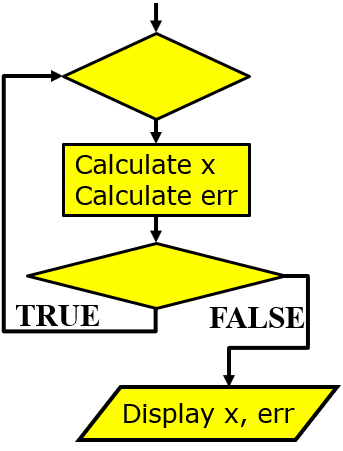

fprintf('The approximate root of %d is %.3f with an error of %.3e.\n', a, x, err)

The approximate root of 5 is 2.236 with an error of 1.929e-05.


## for loop example - Calculating variation

***Which patient shows greater variation?***

patient1 = [88 96 94 98 85 97 89 94 93 87 99 96]; % patient 1 blood oxygen concentration
patient2 = [93 94 95 91 90 93 93 94 94 91 93 95]; % patient 2 blood oxygen concentration

ssP1 = variation(patient1);
ssP2 = variation(patient2);

fprintf('The variation for patient 1 is %d.\nThe variation for patient 2 is %d.', ssP1, ssP2)

The variation for patient 1 is 238.
The variation for patient 2 is 28.


if ssP1>ssP2
    disp('Patient 1''s blood oxygen concentration had more variation')
elseif ssP2>ssP1
    disp('Patient 2''s blood oxygen concentration had more variation')
else
    disp('Both patients had the same blood oxygen concentration variation')
end

Patient 1's blood oxygen concentration had more variation


## Table example 

### bad table

Make vectors of the first 5 integers and their squares.

**Output the results in a table like the one shown.**

`number square`

`------ ------`


number = 1:5;
square = number.^2;

### good table

for n = number
    if n == 1
        fprintf('number sqaure\n')
        fprintf('------ ------\n')
    end
    fprintf('%6d %6d\n', number(n), square(n))
end

number sqaure


------ ------


     1      1
     2      4
     3      9
     4     16
     5     25


## Helper Functions

function v = variation(data)
% VARIATION - calculate the sum of squares of the provided vector
% Input:
%   data - vector containing data for which we are calculating variation
% Output:
%   v - variation based on sum of squares of diff. from the mean



$v=\sum_{k=1}^n {\left(x_k -\bar{x} \right)}^2$          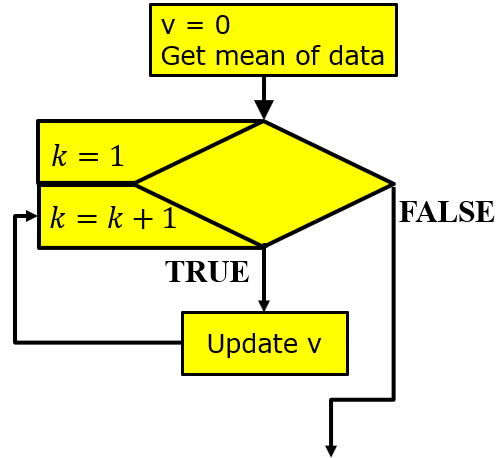

v = 0;
avg = mean(data);

for k = 1:length(data)
    v = v + (data(k)-avg)^2;
end

end